# Run samples of the ServiceQueue simulation(Aj Smith)

Collect statistics and plot histograms along the way.

## Set up

We'll measure time in hours

Arrival rate: 10 per hour

lambda = 40;

Departure (service) rate: 1 per 5 minutes, so 12 per hour

mu = 30;

Number of serving stations

s = 2;

Run 100 samples of the queue.

NumSamples = 100;

Each sample is run up to a maximum time.

MaxTime = 8;

Make a log entry every so often

LogInterval = 1/60;

## Numbers from theory for M/M/1 queue

Compute `P(1+n)` = $P_n$ = probability of finding the system in state $n$ in the long term. Note that this calculation assumes $s=1$.

rho = lambda / mu;
P0 = 0.2;
nMax = 10;
P = zeros([1, nMax+1]);
P(1) = P0;
for n = 1:nMax
    if n < s
    P(1+n) = P0 * rho^n / factorial(n);
    else
        P(n+1) = P0 * rho^n / (factorial(s) * s^(n-s));
    end
end

## Run simulation samples

This is the most time consuming calculation in the script, so let's put it in its own section.  That way, we can run it once, and more easily run the faster calculations multiple times as we add features to this script.

Reset the random number generator.  This causes MATLAB to use the same sequence of pseudo-random numbers each time you run the script, which means the results come out exactly the same.  This is a good idea for testing purposes.  Under other circumstances, you probably want the random numbers to be truly unpredictable and you wouldn't do this.

rng("default");

We'll store our queue simulation objects in this list.

QSamples = cell([NumSamples, 1]);

The statistics come out weird if the log interval is too short, because the log entries are not independent enough.  So the log interval should be long enough for several arrival and departure events happen.

for SampleNum = 1:NumSamples
    fprintf("Working on sample %d\n", SampleNum);
    q = ServiceQueue( ...
        ArrivalRate=lambda, ...
        DepartureRate=mu, ...
        NumServers=s, ...
        LogInterval=LogInterval);
    q.schedule_event(Arrival(random(q.InterArrivalDist), Customer(1)));
    run_until(q, MaxTime);
    QSamples{SampleNum} = q;
end

Working on sample 1
Working on sample 2
Working on sample 3
Working on sample 4
Working on sample 5
Working on sample 6
Working on sample 7
Working on sample 8
Working on sample 9
Working on sample 10
Working on sample 11
Working on sample 12
Working on sample 13
Working on sample 14
Working on sample 15
Working on sample 16
Working on sample 17
Working on sample 18
Working on sample 19
Working on sample 20
Working on sample 21
Working on sample 22
Working on sample 23
Working on sample 24
Working on sample 25
Working on sample 26
Working on sample 27
Working on sample 28
Working on sample 29
Working on sample 30
Working on sample 31
Working on sample 32
Working on sample 33
Working on sample 34
Working on sample 35
Working on sample 36
Working on sample 37
Working on sample 38
Working on sample 39
Working on sample 40
Working on sample 41
Working on sample 42
Working on sample 43
Working on sample 44
Working on sample 45
Working on sample 46
Working on sample 47
Working on sample 48
W

## Collect measurements of how many customers are in the system

Count how many customers are in the system at each log entry for each sample run.  There are two ways to do this.  You only have to do one of them.

### Option one: Use a for loop.

NumInSystemSamples = cell([NumSamples, 1]);
for SampleNum = 1:NumSamples
    q = QSamples{SampleNum};
    % Pull out samples of the number of customers in the queue system. Each
    % sample run of the queue results in a column of samples of customer
    % counts, because tables like q.Log allow easy extraction of whole
    % columns like this.
    NumInSystemSamples{SampleNum} = q.Log.NumWaiting + q.Log.NumInService;
end

### Option two: Map a function over the cell array of ServiceQueue objects.

The `@(q) ...` expression is shorthand for a function that takes a `ServiceQueue` as input, names it `q`, and computes the sum of two columns from its log.  The `cellfun` function applies that function to each item in `QSamples`. The option `UniformOutput=false` tells `cellfun` to produce a cell array rather than a numerical array.

NumInSystemSamples = cellfun( ...
    @(q) q.Log.NumWaiting + q.Log.NumInService, ...
    QSamples, ...
    UniformOutput=false);

## Join numbers from all sample runs.

`vertcat` is short for "vertical concatenate", meaning it joins a bunch of arrays vertically, which in this case results in one tall column.

NumInSystem = vertcat(NumInSystemSamples{:});

MATLAB-ism: When you pull multiple items from a cell array, the result is a "comma-separated list" rather than some kind of array.  Thus, the above means

`NumInSystem = vertcat(NumInSystemSamples{1}, NumInSystemSamples{2}, ...)`

which concatenates all the columns of numbers in NumInSystemSamples into one long column.

This is roughly equivalent to "splatting" in Python, which looks like `f(*args)`.

## Pictures and stats for number of customers in system

Print out mean number of customers in the system.

meanNumInSystem = mean(NumInSystem);
fprintf("Mean number in system: %f\n", meanNumInSystem);

Mean number in system: 2.411223


Make a figure with one set of axes.

fig = figure();
t = tiledlayout(fig,1,1);
ax = nexttile(t);

MATLAB-ism: Once you've created a picture, you can use `hold` to cause further plotting functions to work with the same picture rather than create a new one.

hold(ax, "on");

Start with a histogram.  The result is an empirical PDF, that is, the area of the bar at horizontal index n is proportional to the fraction of samples for which there were n customers in the system.  The data for this histogram is counts of customers, which must all be whole numbers.  The option `BinMethod="integers"` means to use bins $(-0.5, 0.5), (0.5, 1.5), \dots$ so that the height of the first bar is proportional to the count of 0s in the data, the height of the second bar is proportional to the count of 1s, etc. MATLAB can choose bins automatically, but since we know the data consists of whole numbers, it makes sense to specify this option so we get consistent results.

h = histogram(ax, NumInSystem, Normalization="probability", BinMethod="integers");

Plot $(0, P_0), (1, P_1), \dots$.  If all goes well, these dots should land close to the tops of the bars of the histogram.

plot(ax, 0:nMax, P, 'o', MarkerEdgeColor='k', MarkerFaceColor='r');

Add titles and labels and such.

title(ax, "Number of customers in the system");
xlabel(ax, "Count");
ylabel(ax, "Probability");
legend(ax, "simulation", "theory");

Set ranges on the axes. MATLAB's plotting functions do this automatically, but when you need to compare two sets of data, it's a good idea to use the same ranges on the two pictures.  To start, you can let MATLAB choose the ranges automatically, and just know that it might choose very different ranges for different sets of data.  Once you're certain the picture content is correct, choose an x range and a y range that gives good results for all sets of data.  The final choice of ranges is a matter of some trial and error.  You generally have to do these commands *after* calling `plot` and `histogram`.

This sets the vertical axis to go from $0$ to $0.3$.

ylim(ax, [0, 0.3]);

This sets the horizontal axis to go from $-1$ to $21$.  The histogram will use bins $(-0.5, 0.5), (0.5, 1.5), \dots$ so this leaves some visual breathing room on the left.

xlim(ax, [-1, 21]);

MATLAB-ism: You have to wait a couple of seconds for those settings to take effect or `exportgraphics` will screw up the margins.

pause(2);

Save the picture as a PDF file.

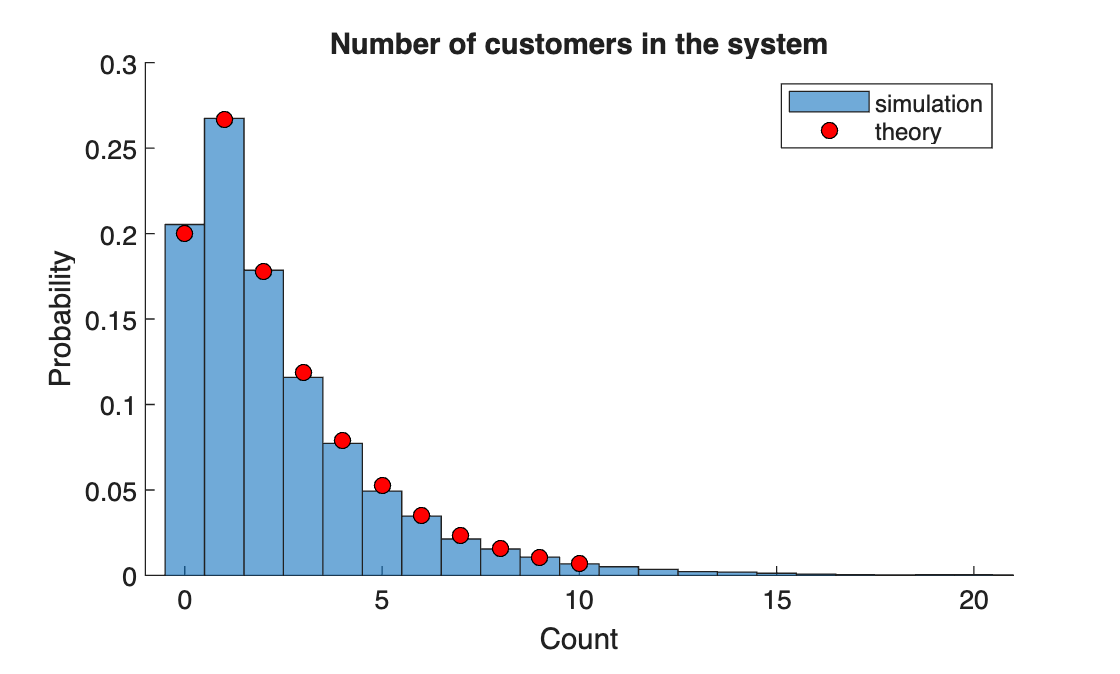

exportgraphics(fig, "Number in system histogram.pdf");

## Collect measurements of how long customers spend in the system

This is a rather different calculation because instead of looking at log entries for each sample `ServiceQueue`, we'll look at the list of served  customers in each sample `ServiceQueue`.

### Option one: Use a for loop.

TimeInSystemSamples = cell([NumSamples, 1]);
for SampleNum = 1:NumSamples
    q = QSamples{SampleNum};
    % The next command has many parts.
    %
    % q.Served is a row vector of all customers served in this particular
    % sample.
    % The ' on q.Served' transposes it to a column.
    %
    % The @(c) ... expression below says given a customer c, compute its
    % departure time minus its arrival time, which is how long c spent in
    % the system.
    %
    % cellfun(@(c) ..., q.Served') means to compute the time each customer
    % in q.Served spent in the system, and build a column vector of the
    % results.
    %
    % The column vector is stored in TimeInSystemSamples{SampleNum}.
    TimeInSystemSamples{SampleNum} = ...
        cellfun(@(c) c.DepartureTime - c.ArrivalTime, q.Served');
end


### Option two: Use `cellfun` twice.

The outer call to `cellfun` means do something to each `ServiceQueue` object in `QSamples`.  The "something" it does is to look at each customer in the `ServiceQueue` object's list `q.Served` and compute the time it spent in the system.

TimeInSystemSamples = cellfun( ...
    @(q) cellfun(@(c) c.DepartureTime - c.ArrivalTime, q.Served'), ...
    QSamples, ...
    UniformOutput=false);

### Join them all into one big column.

TimeInSystem = vertcat(TimeInSystemSamples{:});

## Pictures and stats for time customers spend in the system

Print out mean time spent in the system.

meanTimeInSystem = mean(TimeInSystem);
fprintf("Mean time in system: %f\n", meanTimeInSystem);

Mean time in system: 0.060537


Make a figure with one set of axes.

fig = figure();
t = tiledlayout(fig,1,1);
ax = nexttile(t);

This time, the data is a list of real numbers, not integers.  The option `BinWidth=...` means to use bins of a particular width, and choose the left-most and right-most edges automatically.  Instead, you could specify the left-most and right-most edges explicitly.  For instance, using `BinEdges=0:0.5:60` means to use bins $(0, 0.5), (0.5, 1.0), \dots$

h = histogram(ax, TimeInSystem, Normalization="probability", BinWidth=5/60);

Add titles and labels and such.

title(ax, "Time in the system");
xlabel(ax, "Time");
ylabel(ax, "Probability");

Set ranges on the axes.

ylim(ax, [0, 0.2]);
xlim(ax, [0, 2.0]);

Wait for MATLAB to catch up.

pause(2);

Save the picture as a PDF file.

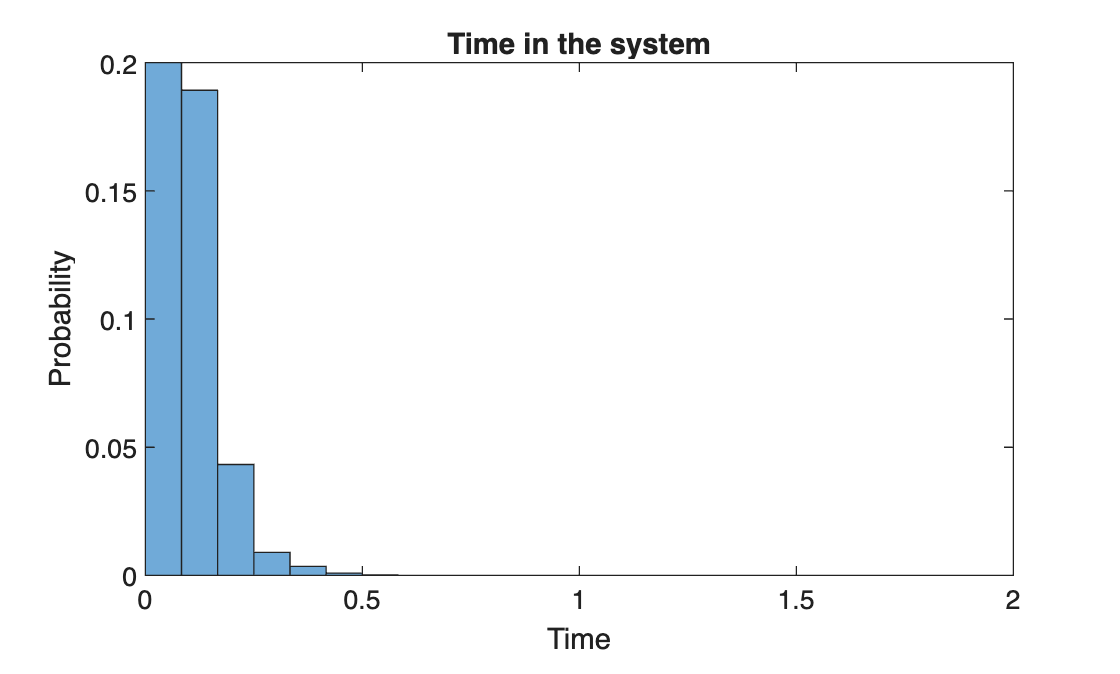

exportgraphics(fig, "Time in system histogram.pdf");